Start speaking


Recording finished


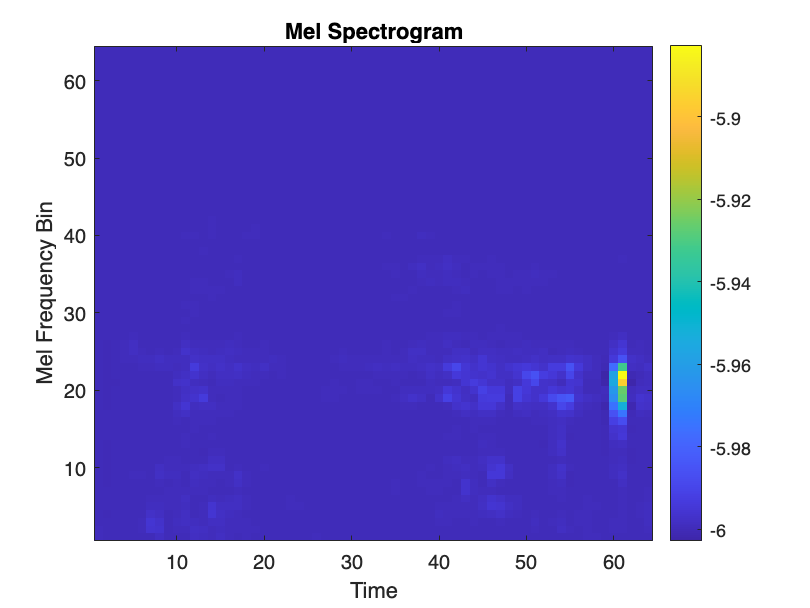

Predicted word: 


     no 



Confidence: 35.5
%

No command recognized


%SVM Demo
figure;
% Load trained model
load("/Users/ericdutan/Documents/GitHub/ML_Project/SVM_Build/svmModel.mat");

% Record audio
recObj = audiorecorder(16000,16,1);

disp("Start speaking")

Start speaking


recordblocking(recObj,1);
disp("Recording finished")

Recording finished


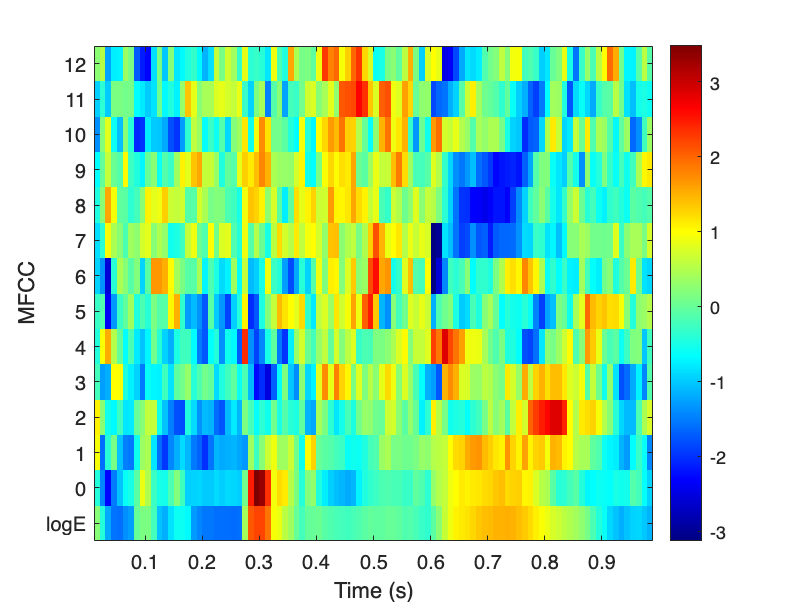


audio = getaudiodata(recObj);

%Convert to mono (just in case)
if size(audio,2) > 1
    audio = mean(audio,2);
end

fs = 16000;

% Extract SAME features as training
coeffs = mfcc(audio, fs);

figure;
mfcc(audio,fs)


feat = [mean(coeffs), std(coeffs)];


% Predict
predictedWord = predict(model, feat);

disp("Predicted word:");

Predicted word:


disp(predictedWord);

     go 

